%% Initialise variables and model
% Some model related variables
clc;
clear;
modelparams = load('model_struct'); 
model = modelparams.model;

ndof = model.nDofs;
nmus = model.nMus;
nstates = 2*ndof + 2*nmus;

% Initialize the model
das3('Initialize',model);

*****************************************************
*                      DAS3MEX                      *
*  (c) 2010-2012 Case Western Reserve University    *
*****************************************************
Initializing...


% Define indices to the state variables within the state vector x
iq = 1:ndof;
iqdot = max(iq) + (1:ndof);
iLce = max(iqdot) + (1:nmus);

%% Insert time start, end and time step
tstep = .003;
tend = 5;
t = 0;
nsteps = round((tend-t)/tstep);

%% Create space for variables
tout = tstep*(0:nsteps)';
xout = zeros(nsteps+1, nstates);
uout = zeros(nsteps+1, 138);
mfout = zeros(nsteps+1, 138);
qTHout = zeros(nsteps+1,3);
error = zeros(nsteps+1,3);
error_int = zeros(nsteps+1,3);

step_u = zeros(nmus,1);
step_xdot = zeros(nstates,1); 
M = zeros(5,1);
exF = zeros(2,1);
handF = rand(3,1);

% Set equilibrium state as initial state
load('C:\Users\s202421\Desktop\DataCreation/w_pos_forces.mat')
x = x_valid(:,2);

lengths = das3('Musclelengths',x);
LCEopt = das3('LCEopt');
SEEslack = das3('SEEslack');
x(iLce) = (lengths - SEEslack)./LCEopt;

xout(1,:) = x';
muscles = 0;

%Initiliase variables
err = [0 0 0]';
ei = [0 0 0]';

% Input Function
u_total = stim_fun(muscles, tstep, tend);

%Reference Value
w_ref = wrist_position(x);
M = zeros(5,1);
exF = zeros(2,1);
handF = [0 0 0]';
j = 0;
while j<30
    for i=1:(nsteps)
        u = u_total(:,i);
    
        % Advance simulation by a step
        [x, step_xdot, step_u,~,qTH] = das3step(x, u, tstep, step_xdot, step_u,M,exF,handF);
        mf = das3('Muscleforces',x);
            
        % store result
        xout(i+1,:) = x';   
        uout(i+1,:) = u';
        mfout(i+1,:) = mf';
        qTHout(i+1,:)=qTH;
        error(i+1,:)=err';
        t = t + tstep;
    
    end
    j = j+1;
    w = wrist_position(x);
    err = w_ref - w;
    disp(err(1,1));

    dt = tstep;
    ei = ei + err*dt;


    % PID Control;
    Kpx = 10;
    Kpy = 10;
    Kpz = -50;

    Kix = 50;
    Kiy = 10;
    Kiz = 10;
    
    handF = [-Kix*ei(1,1)-Kpx*err(1,1)+1 9.8 0]';
end

   -0.2268

   -0.1002

   -0.1070

   -0.1062

   -0.1062

   -0.1060

   -0.1059

   -0.1058

   -0.1057

   -0.1055

   -0.1054

   -0.1053

   -0.1052

   -0.1051

   -0.1050

   -0.1049

   -0.1048

   -0.1047

   -0.1045

   -0.1044

   -0.1043

   -0.1042

   -0.1042

   -0.1041

   -0.1040

   -0.1039

   -0.1038

   -0.1037

   -0.1036

   -0.1035



file_name = 'x5';
create_osim(ndof, model, file_name, tout, xout, mfout);

winit = wrist_position(xout(1,:)');
w_ref;
wend = wrist_position(xout(end,:)');
err = winit-wend;
error(end,:);

x = x_valid(:,2);

moments = das3('Jointmoments', x)

% Plot
plot_error(tout,error);

plot_forces(tout,mfout);

plot_neurexct(tout,xout);

plot_wrist_positions_2D(tout,xout);

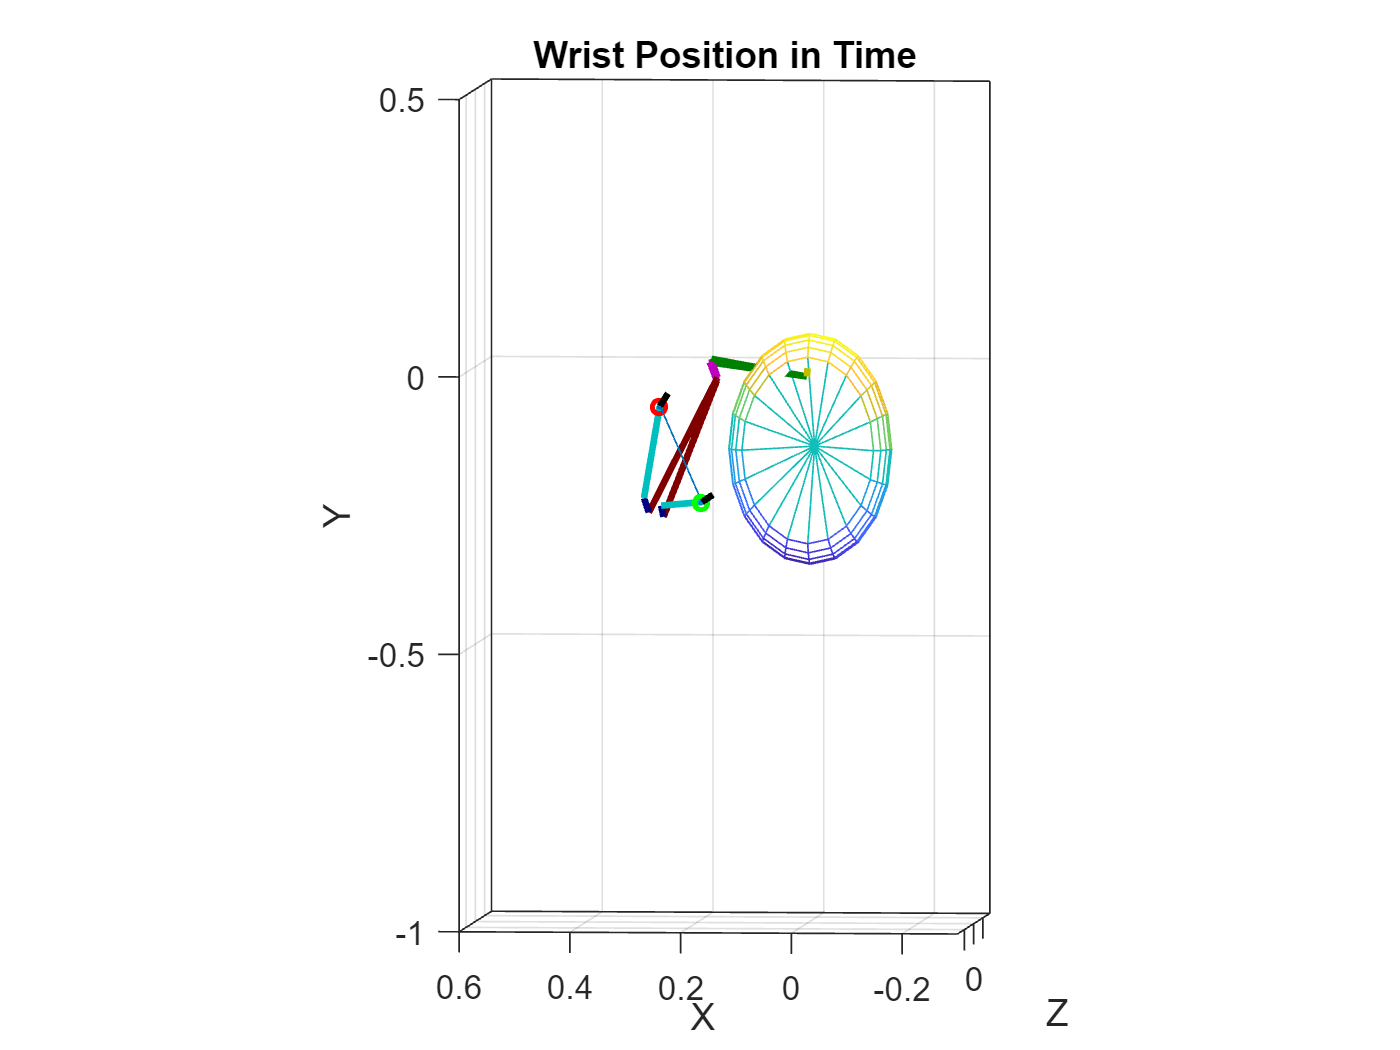

plot_wrist_positions(xout,model);

% Muscle Forces
%mf = das3('Muscleforces',xnew);

% Wrist Position
pos = wrist_position(xnew);

% Set equilibrium state as initial state
load('C:\Users\s202421\Desktop\DataCreation/w_pos_forces.mat')
x = x_valid(:,2);

lengths = das3('Musclelengths',x);
LCEopt = das3('LCEopt');
SEEslack = das3('SEEslack');
x(iLce) = (lengths - SEEslack)./LCEopt;

xout(1,:) = x';
muscles = 0;

%Initiliase variables
err = [0 0 0]';
ei = [0 0 0]';

% Input Function
u_total = stim_fun(muscles, tstep, tend);

%Reference Value
w_ref = wrist_position(x);
M = zeros(5,1);
exF = zeros(2,1);
handF = [0 0 0]';
j = 0;
for i=1:(nsteps)
    u = u_total(:,i);

    % Advance simulation by a step
    [x, step_xdot, step_u,~,qTH] = das3step(x, u, tstep, step_xdot, step_u,M,exF,handF);
    mf = das3('Muscleforces',x);
        
    % store result
    xout(i+1,:) = x';   
    uout(i+1,:) = u';
    mfout(i+1,:) = mf';
    qTHout(i+1,:)=qTH;
    error(i+1,:)=err';
    t = t + tstep;

end
w = wrist_position(x);
err = w_ref - w